## Preamble

Group neural analysis reproductions for "A Novel Neural Prediction Error Found in Anterior Cingulate Cortex Ensembles" (Hyman et al. 2017), Figure 2A. 

The first task is to extract session identifiers from the provided data files and store them in a table for later access: (Assumes directory structure as described in `var_spec.mlx)` 

% edit as needed
base = "C:\Users\talha\Desktop\Benel\hyman2017_reproductions\";
data_folder = "3portdata";

% collating session names
listing = dir(fullfile(base, data_folder, "*.mat"));
session_ids = {listing.name};
session_ids = strrep(session_ids, ".mat", "")';
sessions = table(session_ids, 'VariableNames', ["ID"])

sessions = 16×1 table
                           ID                       
    ________________________________________________

    "aCW8_11_28_12_iFR10ms_dur_thin_durs_10ms"      
    "bPFHPC4_12_06_12_iFR10_dur_thin_durs_10ms"     
    "c7_27_13_H_iFR10_dur_thin_durs_10ms"           
    "d6_28_13_E_iFR10_withstamps_dur_thin_durs_10ms"
    "e7_4_13_E_iFR10ms_dur_thin_durs_10ms"          
    "f7_19_13_H_iFR10ms_dur_thin_durs_10ms"         
    "g7_23_13_H_iFR10ms_dur_thin_durs_10ms"         
    "hCW8_11_23_12_iFR10ms_dur_thin_durs_10ms"      
    "iCW8_11_09_iFR10ms_dur_thin_durs_10ms"         
    "k7_10_12_E_iFR10_stamps_dur_thin_durs_10ms"    
    "l7_16_13_H_iFR10_stmaps_dur_thin_durs_10ms"    
    "m7_17_13_H_iFR10ms_stmaps_dur_thin_durs_10ms"  
    "n7_17_13_E_iFR10_stmaps_dur_thin_durs_10ms"    
    "o7_19_13_E_iFR10_stmaps_dur_thin_durs_10ms"    
    "p8_2_13_PH5_iFR10_stamps_dur_thin_durs_10ms"   
    "qj8_7_13_PH5_iFR10_stamps_dur_thin_du


clear listing session_ids

### Port and ESP inferrence

The provided data files lack explicit documentation of port contingencies (e.g., whether port 1 was the 25/75 port), and at which trials experimenter-defined switch points (ESPs) occurred. I employed the following methods to infer both tidbits:

**Port contingencies. **Port contingencies can be inferred by visualizing a port's initial reward/no reward (R/NR) history (documented in `Event_timestamps`). If the majority of a port's initial R/NR outcomes were rewards, that port was the session's 75/25 port:

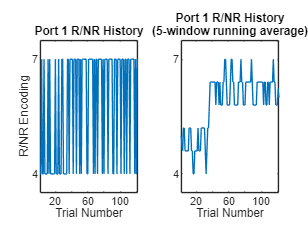

load(fullfile(base, data_folder, sessions.ID(1) + ".mat"), "Event_timestamps");

figure; 
tiledlayout(1, 2);
p1_rnr_idx_mask = ismember(Event_timestamps(:, 3), [4 7]);
p1_rnr = Event_timestamps(p1_rnr_idx_mask, 3); 

nexttile; 
plot(p1_rnr)
title("Port 1 R/NR History");
xlabel("Trial Number");
xlim([1 length(p1_rnr)]);
ylabel("R/NR Encoding");
ylim([3.5 7.5]);
yticks([4 7]);

nexttile; 
plot(movmean(p1_rnr, 5))
title(["Port 1 R/NR History", "(5-window running average)"]);
xlabel("Trial Number");
xlim([1 length(p1_rnr)]);
ylim([3.5 7.5]);
yticks([4 7]);


clear p1_rnr_idx_mask p1_rnr

Though port contingencies can be inferred visually, I wanted to automate this process without relying on visual aids. This automation has the added benefit of creating a reproducible method by which to infer ESPs. 

"Smoothed" (i.e., running average) R/NR histories should be centered around the expected value of a port's R/NR encodings and possible contingencies. For example, if port 1 *was *the 25/75 port, then its pre-ESP `Event_timestamps` should record ~25% Rs (encoded as a 4) and ~75% NRs (encoded as a 7) for an expected running average of .25*4 + .75*7 = 6.25. 

To test whether actual R/NR histories "matched" expected values under a particular contingency hypothesis, I first made a utility function to calculate summary statistics for each such encoding/contingency pair:

% utility statistics functions
function ev = e_v(vs, ps)
    % does not check size(vs) == size(ps)
    ev = sum(vs .* ps); 
end

function sd = s_d(vs, ps)
    % does not check size(vs) == size(ps)
    ev = e_v(vs, ps); 
    sq_diffs = (vs - ev).^ 2;

    sd = sqrt(e_v(sq_diffs, ps));
    clear ev sq_diffs
end

% generates summary statistics 
% over combinations of reward encodings (4/7, 5/8, 6/9) and contingencies (25/75, 50/50, 75/25)
function hyp_stats = stats()
    hyp_stats = zeros(3, 2, 3); 
    vs = zeros(2, 1, 3);
    p25 = [.25 .75]'; 
    p50 = [.5 .5]'; 
    p75 = [.75 .25]'; 

    for i = 1:3
        vs(:, :, i) = [i + 3, i + 6]';
        hyp_stats(:, :, i) = [e_v(vs(:, :, i), p25), s_d(vs(:, :, i), p25); 
                              e_v(vs(:, :, i), p50), s_d(vs(:, :, i), p50); 
                              e_v(vs(:, :, i), p75), s_d(vs(:, :, i), p75)]; 
    end
    clear vs p25 p50 p75 i
end

Then, actual R/NR histories were compared against expected values under each possible encoding/contingency hypothesis. The `movmean_window` controls some level of regularity in R/NR running average histories, and ESPs were assumed to not have occurred before trial 20. This is an imperfect method, and it's possible that different ports could be categorized as having the same contingency identity.

% utility function to identify port contingencies based on R/NR history
% must check whether returned `ids` contain repeated elements
function ids = port_ids(Event_timestamps, movmean_window)
    ids = strings(3, 1); 
    hyp = stats(); 

    % filter for p1/p2 events based off associated r/nr codes
    p1_rnr = ismember(Event_timestamps(:, 3), [4 7]);
    p2_rnr = ismember(Event_timestamps(:, 3), [5 8]); 

    % calculate running averages of R/NR history
    mvm1 = movmean(Event_timestamps(p1_rnr, 3), movmean_window); 
    mvm2 = movmean(Event_timestamps(p2_rnr, 3), movmean_window);

    % classify initial port contingency based off how running averages "sandwich" around expected R/NR values 
    % assumes ESP occurs after trial 20
    if hyp(1, 1, 1) - .25*hyp(1, 2, 1) < mean(mvm1(1:20)) & mean(mvm1(1:20)) < hyp(1, 1, 1) + .25*hyp(1, 2, 1)
        ids(1) = "25%"; 
    elseif hyp(2, 1, 1) - .25*hyp(2, 2, 1) < mean(mvm1(1:20)) & mean(mvm1(1:20)) < hyp(2, 1, 1) + .25*hyp(2, 2, 1)
        ids(1) = "50%"; 
    else 
        ids(1) = "75%"; 
    end

    if hyp(1, 1, 2) - .25*hyp(1, 2, 2) < mean(mvm2(1:20)) & mean(mvm2(1:20)) < hyp(1, 1, 2) + .25*hyp(1, 2, 2)
        ids(2) = "25%"; 
    elseif hyp(2, 1, 2) - .25*hyp(2, 2, 2) < mean(mvm2(1:20)) & mean(mvm2(1:20)) < hyp(2, 1, 2) + .25*hyp(2, 2, 2)
        ids(2) = "50%"; 
    else 
        ids(2) = "75%"; 
    end
    
    rs = ["25%", "50%", "75%"]'; 
    ids(3) = rs(find(~ismember(rs, ids), 1)); 

    clear hyp p1_rnr p2_rnr mvm1 mvm2 rs
end

**ESP onset. **ESPs can be inferred by identifying the point at which running average R/NR histories at either a 25/75 or 75/25 port "flip" around the 50/50 average for said port.

% infers ESP based off where running average 'flips' about 50-50 R/NR value
% should not be run on control ("50%") port
function esp = infer_esp(Event_timestamps, port_id)
    pi_rnr = ismember(Event_timestamps(:, 3), [port_id + 3, port_id + 6]);
    mvm = movmean(Event_timestamps(pi_rnr, 3), 5); 
    hyp = stats(); 

    % assumes ESP occurs after trial 20
    mask = mvm(20:end) < hyp(2, 1, port_id); 
    esp = 20 + find(mask == mask(end), 1); 

    clear pi_rnr mvm hyp mask
end

disp("The inferred ESP for session 1 occured at trial " + infer_esp(Event_timestamps, 1))

The inferred ESP for session 1 occured at trial 37


clear Event_timestamps

### Putting it together

Looping over sessions to collect IDs, inferred ESPs, and actual ESPs: 

% infer port IDs and ESPs
port_id = strings(3, 1, 16);
port = zeros(1, 16);
inferred_esps = zeros(1, 16);
for i = 1:height(sessions)
    load(fullfile(base, data_folder, sessions.ID(i) + ".mat"), "Event_timestamps"); 
    port_id(:, :, i) = port_ids(Event_timestamps, 10);

    port(i) = find(~ismember(port_id(:, :, i), ["50%"]), 1);
    inferred_esps(i) = infer_esp(Event_timestamps, port(i)); 
end
sessions.InferredESP = inferred_esps'

sessions = 16×2 table
                           ID                           InferredESP
    ________________________________________________    ___________

    "aCW8_11_28_12_iFR10ms_dur_thin_durs_10ms"              37     
    "bPFHPC4_12_06_12_iFR10_dur_thin_durs_10ms"             21     
    "c7_27_13_H_iFR10_dur_thin_durs_10ms"                   32     
    "d6_28_13_E_iFR10_withstamps_dur_thin_durs_10ms"        33     
    "e7_4_13_E_iFR10ms_dur_thin_durs_10ms"                  34     
    "f7_19_13_H_iFR10ms_dur_thin_durs_10ms"                 34     
    "g7_23_13_H_iFR10ms_dur_thin_durs_10ms"                 35     
    "hCW8_11_23_12_iFR10ms_dur_thin_durs_10ms"              49     
    "iCW8_11_09_iFR10ms_dur_thin_durs_10ms"                 22     
    "k7_10_12_E_iFR10_stamps_dur_thin_durs_10ms"            38     
    "l7_16_13_H_iFR10_stmaps_dur_thin_durs_10ms"            51     
    "m7_17_13_H_iFR10ms_s


load(fullfile(base, "SwitchTrials.mat"), "SwTrial"); 
sessions.ESP = SwTrial(:, 1); 

clear i Event_timestamps port inferred_esps

To clear the `port_id` string array, I reshaped it to fit the height of sessions and added it to our table. The choice of reshaping, then transposing arises from MATLAB's column-major reshape of `port_id`; if I had directly reshaped to a 16x3 array, our resulting rows would not correspond to each session.  

port_id = reshape(port_id, [3 16])'; 
sessions.P1 = port_id(:, 1); 
sessions.P2 = port_id(:, 2); 
sessions.P3 = port_id(:, 3); 
sessions

sessions = 16×6 table
                           ID                           InferredESP    ESP     P1       P2       P3  
    ________________________________________________    ___________    ___    _____    _____    _____

    "aCW8_11_28_12_iFR10ms_dur_thin_durs_10ms"              37          50    "75%"    "25%"    "50%"
    "bPFHPC4_12_06_12_iFR10_dur_thin_durs_10ms"             21          51    "25%"    "75%"    "50%"
    "c7_27_13_H_iFR10_dur_thin_durs_10ms"                   32          35    "50%"    "25%"    "75%"
    "d6_28_13_E_iFR10_withstamps_dur_thin_durs_10ms"        33          35    "75%"    "25%"    "50%"
    "e7_4_13_E_iFR10ms_dur_thin_durs_10ms"                  34          41    "25%"    "75%"    "50%"
    "f7_19_13_H_iFR10ms_dur_thin_durs_10ms"                


clear port_id

Rudimentary check of uniquely inferring port contignecies: 

num_ports_inferred = zeros(16, 1); 
for i = 1:height(sessions)
    u = unique([sessions.P1(i), sessions.P2(i), sessions.P3(i)]);
    num_ports_inferred(i) = size(u, 2); 
end

num_ports_inferred

num_ports_inferred =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


clear i u 

If `num_ports_inferred` contains only 3s, we can clear it: 

clear num_ports_inferred

Rudimentary check of correctly inferring ESPs: 

% check mean and SD match reported value in paper 
mean(sessions.ESP), std(sessions.ESP)

ans = 48.3750

ans = 17.7384

## Fig 2: Behavioral Analyses

### **Fig 2A: Distribution of unsolicited NPs imply learned port-reward contingencies**

Our task is to find "the number of unsolicited 'checking' responses (i.e., NPs [nose pokes] at a port where the cue light was **not** illuminated) at each port that occurred during steady-state performance (i.e., the final 20 trials before the ESP and the final 20 trials of the session)" (p. 448, bold added for emphasis). 

                                                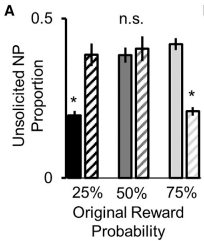

The definition states that we check for NPs at those ports *where* the cue light was not illuminated. For example, given the `Event_timestamps` sequence `10-1-4`, we need only check for NPs at the 50% and 75% ports during the trial. (I emphasize *where *in that earier sentence to exclude the more convoluted interpretation of checking for NPs *while *the cue light was not illuminated, which could include - for the provided example - NPs at the 25% port during the ITI, etc. This is a difficult interpretation for reproduction's sake, since it is impossible to determine when the cue light turned off for a given trial with the provided data. It is also an undesirable interpretation since NPs at the solicited port *after *the cue light could be the result of picking up crumbs, etc. - i.e., they could very well be solicited.) 

The reported analysis facets unsolicited pokes by port probability (25%, 50%, 75%) and trial block (pre-/post-ESP). It appears that unsolicited NP rates (`unpr`s) were calculated with reference to trial block, i.e., the pre-ESP `unpr` at the 25% port was found by taking the total of unsolicited nose pokes at the 25% port and dividing by the total of unsolicited nose pokes elsewhere, over all trials of all sessions. It would seem natural to consider the total *number *of unsolicited nose pokes, but since the data is recorded in time bins I instead consider the total *duration *of unsolicited nose pokes. (So-called unsolicited NP durations, or `unpd`s.)

These considerations stated, I attempted to reproduce Fig. 2A: 

unprs = zeros(height(sessions), 7); 
for i = 1 : height(sessions)
    load(fullfile(base, data_folder, sessions.ID(i) + ".mat"));
    num_trials = floor(size(Event_timestamps, 1) / 3);

    % calculate unpds for each trial
    init_ids = sessions{i, ["P1", "P2", "P3"]}; 
    session_i_unpds = calc_unpds(Event_timestamps, Tv1, init_ids, sessions.InferredESP(i), Poke_Entries25, Poke_Entries50, Poke_Entries75);

    % calculate unprs for session i by trial block and port
    unprs(i, :) = [i calc_unprs(sessions.InferredESP(i), session_i_unpds)]; 

    clearvars -except base data_folder sessions unprs
end

varnames = ["session", "pre25", "pre50", "pre75", "post25", "post50", "post75"]; 
unprs = array2table(unprs, VariableNames = varnames)

unprs = 16×7 table
    session     pre25      pre50       pre75       post25        post50      post75 
    _______    _______    ________    ________    _________    __________    _______

       1             0           0           1      0.47084      0.014541    0.51462
       2       0.45949      0.2959     0.24462      0.45589       0.25524    0.28887
       3             0     0.54343     0.45657      0.36049       0.37528    0.26422
       4       0.16788     0.71779     0.11434      0.48618       0.10034    0.41347
       5       0.11258     0.58621     0.30122      0.30842       0.43746    0.25412
       6       0.14722     0.76367    0.089109      0.13248       0.48181    0.38571
       7       0.12901     0.43878     0.43222      0.44268   

clear varnames

Averaging over sessions and calculating standard errors on the means: 

avg_unprs = [mean(unprs.pre25), mean(unprs.pre50), mean(unprs.pre75);
             mean(unprs.post25), mean(unprs.post50), mean(unprs.post75)]; 
se_unprs = [std(unprs.pre25), std(unprs.pre50), std(unprs.pre75);
            std(unprs.post25), std(unprs.post50), std(unprs.post75)];
sem_unprs = (1 / sqrt(height(unprs))) * se_unprs; 
clear se_unprs

Finally, plotting the results: 

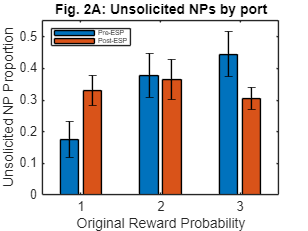

figure; 

cats = ["25%" "50%" "75%"];
b = bar(avg_unprs', 'grouped'); 

hold on

[ngroups, nbars] = size(avg_unprs'); 
x = nan(nbars, ngroups); 
for i = 1:nbars 
    x(i,:) = b(i).XEndPoints; 
end
errorbar(x',avg_unprs',sem_unprs','k','linestyle','none'); 

xlabel("Original Reward Probability");
ylabel("Unsolicited NP Proportion");
legend("Pre-ESP", "Post-ESP", 'Location', 'northwest', 'Fontsize', 5);
title("Fig. 2A: Unsolicited NPs by port");
axis padded

hold off

clear cats avg_unprs ngroups nbars x i sem_unprs

We see that SEMs suggest statistically significant results for the 25/75 and 75/25 ports and that UNPRs increase (post-ESP) in the former port and decrease in the latter. In other words, **general trends hold! **But (1) error bars appear much larger than and (2) precise proportions on each bar don't seem to match those published in Fig. 2A. 

These differences may be due to a number of factors, at a range of levels. For example, 

- *Assumptions. *Perhaps NP counts, as opposed to durations, would have been more appropriate to calculate. After all, a rat with 50 rapid, unsolicited NPs in a trial could reasonably be said to be more "expectant" than a rat with 2 unsolicited NPs over the same duration. 

- *Outliers. *Occasionally, some sessions recorded upwards of 5 mins. for a single trial. Perhaps UNPs during these trials were excluded from further analysis. 

- *Ambiguity in data organization. *The provided `SwitchTrials.mat` file does not clearly document which record of ESPs ought to be used for analysis. 

- *Algorithms*. The `infer_esp` routine necessarily introduces uncertainty in downstream analysis. 

#### Statistical Significance Tests

Now I attempt to reproduce the stated 2-way ANOVA results. Here, I use `anovan` with default fixed effects:

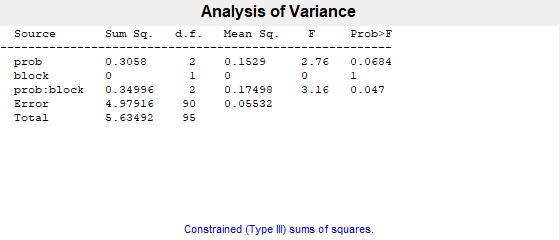

p =     0.0684
    1.0000
    0.0470


session_unprs = removevars(unprs, "session"); 
session_unprs = table2array(session_unprs); 

probs25 = repmat(["25"], 1, height(unprs));
probs50 = repmat(["50"], 1, height(unprs)); 
probs75 = repmat(["75"], 1, height(unprs)); 
pres = repmat(["pre"], 1, 3 * height(unprs)); 
posts = repmat(["post"], 1, 3 * height(unprs));


probs = repmat([probs25 probs50 probs75], 1, 2); 
blocks = [pres posts]; 
p = anovan(reshape(session_unprs, 1, []), {probs blocks},'model',2,'varnames',{'prob','block'})

clear session_unprs probs25 probs50 probs75 pres posts probs blocks p

At p = .048 < .05 for the interaction `prob*block` effect, `anovan` preliminarily suggests statistical significance in our results. Post-hoc analysis is required to confirm that the 25/75 and 75/25 results are indeed statistically significant, but I omit that analysis on the basis of naivete. (For now!)